clear;
path_opt= readtable('path_opt.csv');

path_opt_slow= readtable('path_opt_slowsteer.csv');


path_time= readtable('path_minitime.csv');

path_time_slow= readtable('path_minitime_slowsteer.csv');


path_center= readtable('path_center.csv');

track_outer=readtable('bound_outer.csv');

track_inner=readtable('bound_inner.csv');

% s_center= readtable('spline_center.csv');


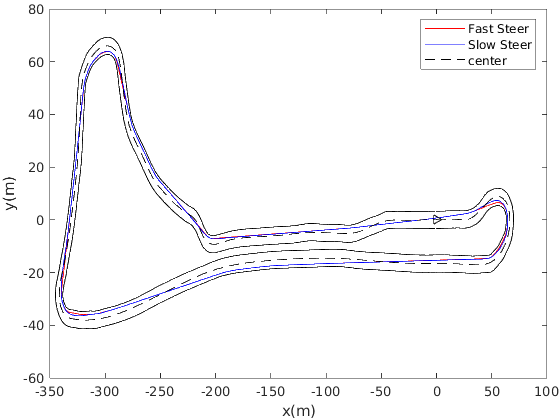

close all;
figure();
plot(path_opt.x_Path_x, path_opt.path_y, "Color", "red");
hold on;
plot(path_opt_slow.x_Path_x, path_opt_slow.path_y, "Color", "blue");
hold on;
plot(path_center.x_Path_x, path_center.path_y, "Color", "black", "LineStyle","--");
hold on;
plot(path_center.x_Path_x(1), path_center.path_y(1), "Marker", ">", "Color", "black");
hold on;
plot(track_inner.x_Inner_x, track_inner.inner_y, "Color", "black")
hold on;
plot(track_outer.x_Outer_x, track_outer.outer_y, "Color", "black")
hold off;
legend('Fast Steer', 'Slow Steer', 'center')
xlabel("x(m)")
ylabel("y(m)")
set(gca,'LooseInset',get(gca,'TightInset'))

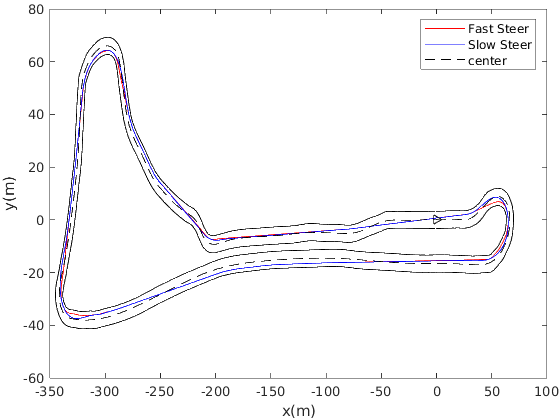

close all;
figure();
plot(path_time.x_Path_x, path_time.path_y, "Color", "red");
hold on;
plot(path_time_slow.x_Path_x, path_time_slow.path_y, "Color", "blue");
hold on;
plot(path_center.x_Path_x, path_center.path_y, "Color", "black", "LineStyle","--");
hold on;
plot(path_center.x_Path_x(1), path_center.path_y(1), "Marker", ">", "Color", "black");
hold on;
plot(track_inner.x_Inner_x, track_inner.inner_y, "Color", "black")
hold on;
plot(track_outer.x_Outer_x, track_outer.outer_y, "Color", "black")
hold off;
legend('Fast Steer', 'Slow Steer', 'center')
xlabel("x(m)")
ylabel("y(m)")
set(gca,'LooseInset',get(gca,'TightInset'))

% figure();
% num=402:558;
% s_cum= cumsum(s_center.x_Ds);
% plot(s_cum(num), k_opt.x_Kappa(num), "Color", "red");
% hold on;
% plot(s_cum(num), k_opt_05.x_Kappa(num), "Color", "blue");
% hold on;
% plot(s_cum(num), k_opt_01.x_Kappa(num), "Color", "green");
% hold on;
% % plot(cumsum(s_center.x_Ds), k_center.x_Kappa, "Color", "black");
% % hold on; 
% 
% hold off;
% grid on; grid minor;
% legend('\mu=0.9', '\mu=0.5', '\mu=0.1')
% xlabel("distance(m)")
% ylabel("Curvature \kappa")
% set(gca,'LooseInset',get(gca,'TightInset'))


% plot(s_cum(num), k_time.x_Kappa(num), "Color", "red");
% hold on;
% plot(s_cum(num), k_time_05.x_Kappa(num), "Color", "blue");
% hold on;
% plot(s_cum(num), k_time_01.x_Kappa(num), "Color", "green");
% hold on;
% % plot(cumsum(s_center.x_Ds), k_center.x_Kappa, "Color", "black");
% % hold on; 
% 
% hold off;
% grid on; grid minor;
% legend('\mu=0.9', '\mu=0.5', '\mu=0.1')
% xlabel("distance(m)")
% ylabel("Curvature \kappa")
% set(gca,'LooseInset',get(gca,'TightInset'))
